# Autonomie Chapitre 3 

## Iluustration Comportement Assymptotique

`Soit `$$(X_n)_{n\geq 1}$$` une suite de v.a.r.`

`définies`` sur `$$\Omega$$` . On note `$\[\overline X_n=\frac{X_1+...+X_n}{n}.\]$` On souhaite étudier la limite de `$$\overline X_n$$`, ainsi que sa distribution. `

- `Ecrire un script matlab qui renvoie `$$\overline X_n$$` pour `$$n$$` fixé et lorsque  `$$(X_n)_{n\geq 1}$$` suit une loi géométrique de paramètre `$ $1/4$$.  

`Attention :  Dans matlab la loi géométrique compte le nombre d'échecs avant un succès et non pas comme dans le poly le rang d'apparition du premier succès. `

clear

% simulation de n réalisations d'une loi des grands nombres géométrique 
% de paramètre 1/4
n=1000;
x=1+geornd(0.25,1,1000); %vecteur ligne de taille 1000

%ou  

pdf1 =makedist('NegativeBinomial','R',1,'p',0.25)
u = 1+random(pdf1, 1000, 1); % vecteur colonne de taille 1000

- `Tracer `$$\overline X_n$$` en fonction de n pour `$$n \in [1,100]$$`.`

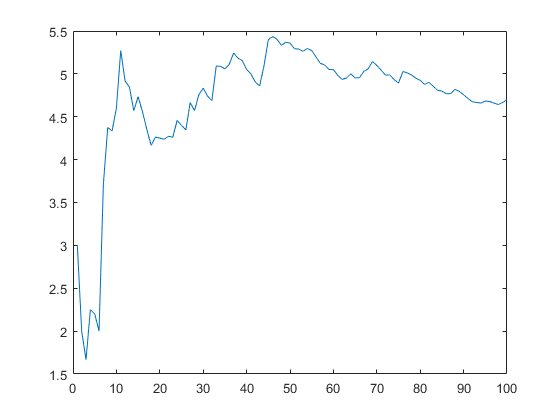

N=100;
xbarre_n=zeros(1,N);
xbarre=0;
for i=1:N
x=1+geornd(0.25,1,1);
xbarre=1/i*((i-1)*xbarre+x);
xbarre_n(i)=xbarre;
end
plot(xbarre_n)

- ` Refaire la même chose pour une loi uniforme sur [O,1]. `

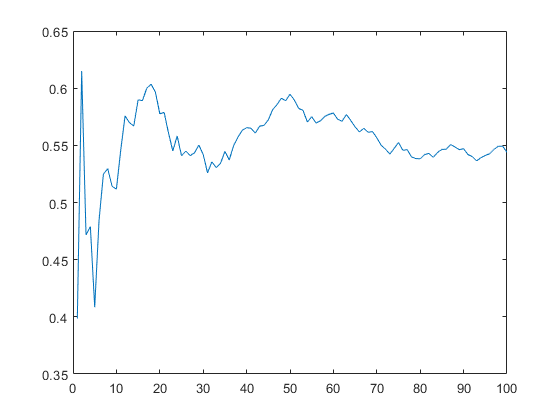

N=100;
xbarre_n=zeros(1,N);
xbarre=0;
for i=1:n
x=unifrnd(0,1);
xbarre=1/i*((i-1)*xbarre+x);
xbarre_n(i)=xbarre;
end
plot(xbarre_n)

- `On fixe `$$N=100$$`. Tracer l'histogramme pour `$$Nsimu=10000$$` valeurs de `$$\overline X_N$$`. Qu'observez-vous dans les deux cas (loi géométrique et loi uniforme) ?`

N=100;
Nsimu=10000

Nsimu = 10000

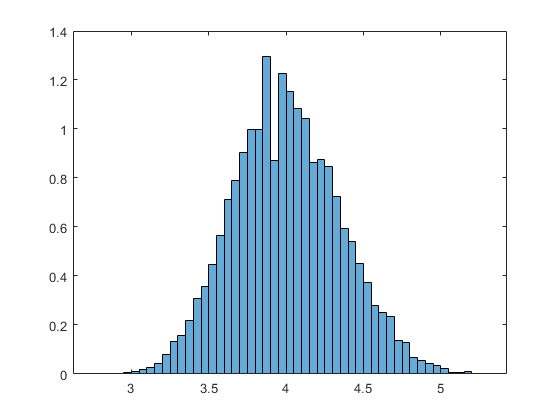


vect_xbarre=mean(1+geornd(0.25,Nsimu,N),2); % le paramètre 2 dans mean est 
% pour calculer la moyenne suivant les colonnes
histogram(vect_xbarre,'Normalization','pdf')

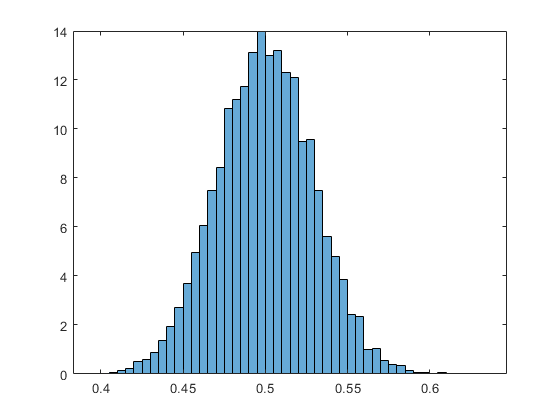


%code nonvectorialisé
% vect_xbarre=[];
% xbarre=0;
% for i=1:Nsimu
% xbarre=mean(1+geornd(0.25,1,N));
% vect_xbarre=[vect_xbarre,xbarre];
% end
% histogram(vect_xbarre,'Normalization','pdf')


vect_xbarre=mean(unifrnd(0,1,Nsimu,N),2);% le paramètre 2 dans mean est 
% pour calculer la moyenne suivant les colonnes
histogram(vect_xbarre,'Normalization','pdf')

### Activité 2 Simulation :Loi triangulaire

`Exécuter les dexu codes suivants  ``triangulaire1`` et ``triangulaire2`` qui simulent `$$n$$` réalisations d'une loi triangulaire de paramètre `$$(a,b,c)$$` et tracer l'histogramme. On note `$$f$$` la densité`$\[f(x)=1_{[a;c]}(x)\frac{2(x-a)}{(b-a)(c-a)}+1_{[c;b]}(x)\frac{2(b-x)}{(b-a)(b-c)}\]$` et `$$F$$` la fonction de répartition de cette loi. `

%Triangulaire 1
clear
clf
Nsimu=10000;
a=0;
b=1;
c=0.5;
u=unifrnd(0,1,Nsimu,1);
x=b-sqrt((1-u)*(b-a)*(b-c));
x(u<((c-a)/(b-a)))=a+sqrt(u(u<((c-a)/(b-a)))*(b-a)*(c-a));
histogram(x,'Normalization','pdf') 
title('Première méthode')

- ` Que représente le paramètre `$$c$$` pour la variable aléatoire ?`

- ` Retrouver le lien entre la variable simulée `$$X$$` et la variable aléatoire `$$U$$` uniforme sur ``[0,1]`` en utilisant la densité `$$f$$`, la fonction de répartition `$$F$$` ou la fonction de répartition inverse `$$F^{-1}$$`.`

%traingulaire 2
clear
Nsimu=10000;
a=0;
b=1;
c=0.5;
m=2/(b-a);
i=0;
while i<Nsimu
u=unifrnd(a,b);
v=unifrnd(0,m);
f=2/(b-a)*(b-u)/(b-c);
f(u<c)=2/(b-a)*(u(u<c)-a)/(c-a);
if v<f
     x(i+1)=u;
     i=i+1;
 end
end
histogram(x,'Normalization','pdf')
title('Deuxième méthode')

- ` Que représente le réel `$$m$$` ? `

- ` Dans la deuxième méthode, pour simuler une réalisation de `$$X$$` combien d'appel en moyenne à la fonction ``unifrnd`` fait-on ? `